clc; clear; close all; addpath z_toolbox;
load(fullfile("step8_IEDtravelingWave_corrSelect", ...
    "IEDtw_meth-corrSelect_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat"));
[~, order_opt] = max(mean(adjR2_twDED_as, 1));
disp(order_opt);

     6



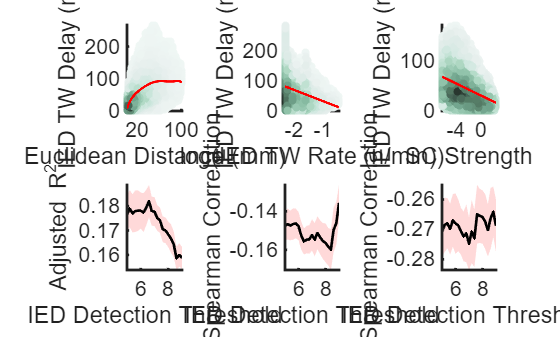

load(fullfile('step8_IEDtravelingWave_corrSelect', ...
    'IEDtw_meth-corrSelect_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'EDas', 'IEDtwDas');
[forest, tf, scores] = iforest([EDas, IEDtwDas], "ContaminationFraction", 0.1);
EDas = EDas(scores <= forest.ScoreThreshold);
IEDtwDas = IEDtwDas(scores <= forest.ScoreThreshold);
[polyModel, Curve, Ftest] = f_polyfit(EDas, IEDtwDas, order_opt);
subplot(2, 3, 1);
f_densityScatter(EDas, IEDtwDas, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(EDas), max(EDas)]); ylim([min(IEDtwDas), max(IEDtwDas)]);
xlabel('Euclidean Distance (mm)'); ylabel('IED TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
clear;
load(fullfile('step8_IEDtravelingWave_corrSelect', ...
    'IEDtw_meth-corrSelect_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'IEDtwRas', 'IEDtwDas');
[forest, tf, scores] = iforest([IEDtwRas, IEDtwDas], "ContaminationFraction", 0.1);
IEDtwRas = IEDtwRas(scores <= forest.ScoreThreshold);
IEDtwDas = IEDtwDas(scores <= forest.ScoreThreshold);
[~, Curve, ~] = f_polyfit(IEDtwRas, IEDtwDas, 1);
subplot(2, 3, 2); 
f_densityScatter(IEDtwRas, IEDtwDas, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(IEDtwRas), max(IEDtwRas)]);
ylim([min(IEDtwDas), max(IEDtwDas)]);
xlabel('log(IED TW Rate (n/min))'); ylabel('IED TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
clear;
load(fullfile('step8_IEDtravelingWave_corrSelect', ...
    'IEDtw_meth-corrSelect_TD-6d0_polyfit1000-fibnVSdelay.mat'), ...
    'IEDtwDas', 'fibNas');
[forest, tf, scores] = iforest([fibNas, IEDtwDas], "ContaminationFraction", 0.1);
fibNas = fibNas(scores <= forest.ScoreThreshold);
IEDtwDas = IEDtwDas(scores <= forest.ScoreThreshold);
[~, Curve, ~] = f_polyfit(fibNas, IEDtwDas, 1);
subplot(2, 3, 3);
f_densityScatter(fibNas, IEDtwDas, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(fibNas), max(fibNas)]); 
ylim([min(IEDtwDas), max(IEDtwDas)]);
xlabel('SC Strength'); ylabel('IED TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
clear;
path = 'step8_IEDtravelingWave_corrSelect';
TDstr = {'5d0', '5d2', '5d4', '5d6', '5d8', '6d0', '6d2', '6d4', '6d6', '6d8', ...
        '7d0', '7d2', '7d4', '7d6', '7d8', '8d0', '8d2', '8d4', '8d6', '8d8', '9d0'};
TD = 5:0.2:9;
for nTD = 1:length(TD)
    load(fullfile(path, ['IEDtw_meth-corrSelect_TD-', TDstr{nTD}, '_polyfit.mat']), 'adjR2_twDED_as');
    A = adjR2_twDED_as(:, 6);
    Vmean1(nTD) = mean(A(:), 'omitnan'); 
    Vstd1(nTD) = std(A(:), 'omitnan');
    load(fullfile(path, ['IEDtw_meth-corrSelect_TD-', TDstr{nTD}, '_polyfit.mat']), 'R_twDR_as');
    Vmean2(nTD) = mean(R_twDR_as, 'omitnan'); 
    Vstd2(nTD) = std(R_twDR_as, 'omitnan');
    load(fullfile(path, ['IEDtw_meth-corrSelect_TD-', TDstr{nTD}, '_polyfit-fibnVSdelay.mat']), 'R_fibNtwD_as');
    Vmean3(nTD) = mean(R_fibNtwD_as, 'omitnan'); 
    Vstd3(nTD) = std(R_fibNtwD_as, 'omitnan');
end
errorShadowX = [TD, fliplr(TD)];
subplot(2, 3, 4);
errorShadowY_upper = Vmean1+Vstd1; 
errorShadowY_lower = Vmean1-Vstd1;
errorShadowY = [errorShadowY_upper, fliplr(errorShadowY_lower)];
fill(errorShadowX, errorShadowY, [1, 0.5, 0.5], 'FaceAlpha', 0.3,  'EdgeColor', 'none'); hold on;
plot(TD, Vmean1, 'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0, 0]); hold off;
xlim([5, 9]); ylabel("Adjusted R^2"); xlabel("IED Detection Threshold");
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
subplot(2, 3, 5);
errorShadowY_upper = Vmean2 + Vstd2; errorShadowY_lower = Vmean2 - Vstd2;
errorShadowY = [errorShadowY_upper, fliplr(errorShadowY_lower)];
fill(errorShadowX, errorShadowY, [1, 0.5, 0.5], 'FaceAlpha', 0.3,  'EdgeColor', 'none'); hold on;
plot(TD, Vmean2, 'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0, 0]); hold off;
xlim([5, 9]); ylabel("Spearman Correlation"); xlabel("IED Detection Threshold");
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
subplot(2, 3, 6);
errorShadowY_upper = Vmean3 + Vstd3; errorShadowY_lower = Vmean3 - Vstd3;
errorShadowY = [errorShadowY_upper, fliplr(errorShadowY_lower)];
fill(errorShadowX, errorShadowY, [1, 0.5, 0.5], 'FaceAlpha', 0.3,  'EdgeColor', 'none'); hold on;
plot(TD, Vmean3, 'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0, 0]); hold off;
xlim([5, 9]); ylabel("Spearman Correlation"); xlabel("IED Detection Threshold");
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);